data = readtable("Interpolated_perpendicular_distance.csv");
data = [data.Left_avg, data.Right_avg, data.x];

data1 = table2array(readtable("csv/Perpendicular Distance/Run 1.csv"));
data2 = table2array(readtable("csv/Perpendicular Distance/Run 2.csv"));
data3 = table2array(readtable("csv/Perpendicular Distance/Run 3.csv"));
data4 = table2array(readtable("csv/Perpendicular Distance/Run 4.csv"));
data5 = table2array(readtable("csv/Perpendicular Distance/Run 5.csv"));
data = vertcat(data1,data2,data3,data4,data5)

data = 	1.0e+03 *

         0    4.3480    5.9920    0.0110         0         0         0
    0.0010    4.1720    5.8840    0.0110    0.0006         0         0
    0.0020    3.6840    4.3400    0.0080    0.0011         0         0
    0.0030    1.6560    2.3520    0.0040    0.0015         0         0
    0.0040    0.7040    0.9160    0.0020    0.0022         0    0.0000
    0.0050    0.4760    0.5720    0.0010    0.0032    0.0000    0.0000
    0.0060    0.4000    0.4600    0.0010    0.0041    0.0000    0.0000
    0.0070    0.3760    0.4080    0.0010    0.0050    0.0000    0.0000
    0.0080    0.3760    0.3960    0.0010    0.0059    0.0000    0.0000
    0.0090    0.3840    0.4040    0.0010    0.0069    0.0001    0.0000


data = data(20:end-10,:);
[~,is]=sort(data(:,5));
data=data(is,:);

data = data(110:end,:);

x = data(:,5);
yl = data(:,1);
yr = data(:,2);
y = (yl+yr)/2;

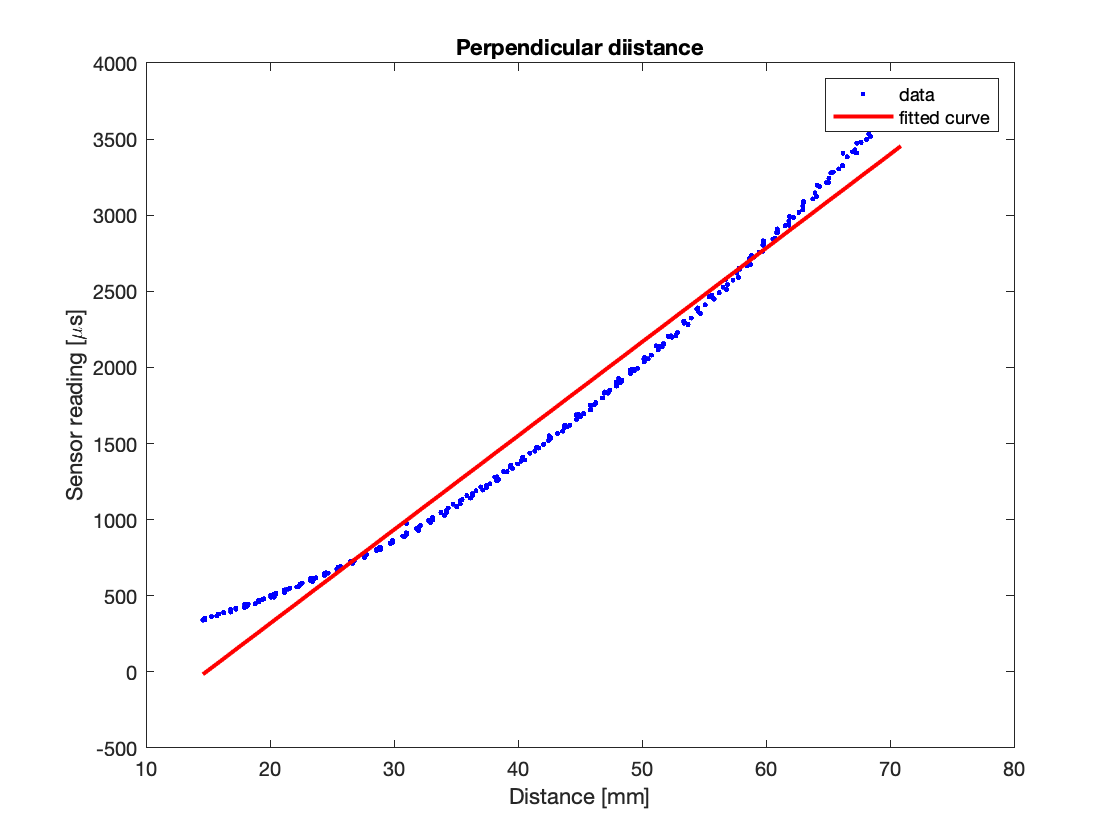

[f_pol,gof_pol] = fit(x,y,'poly1');
figure
h_pol= plot(f_pol, x, y);
set(h_pol, 'LineWidth', 2);
ylabel('Sensor reading [\mus]')
xlabel('Distance [mm]')
title('Perpendicular diistance')